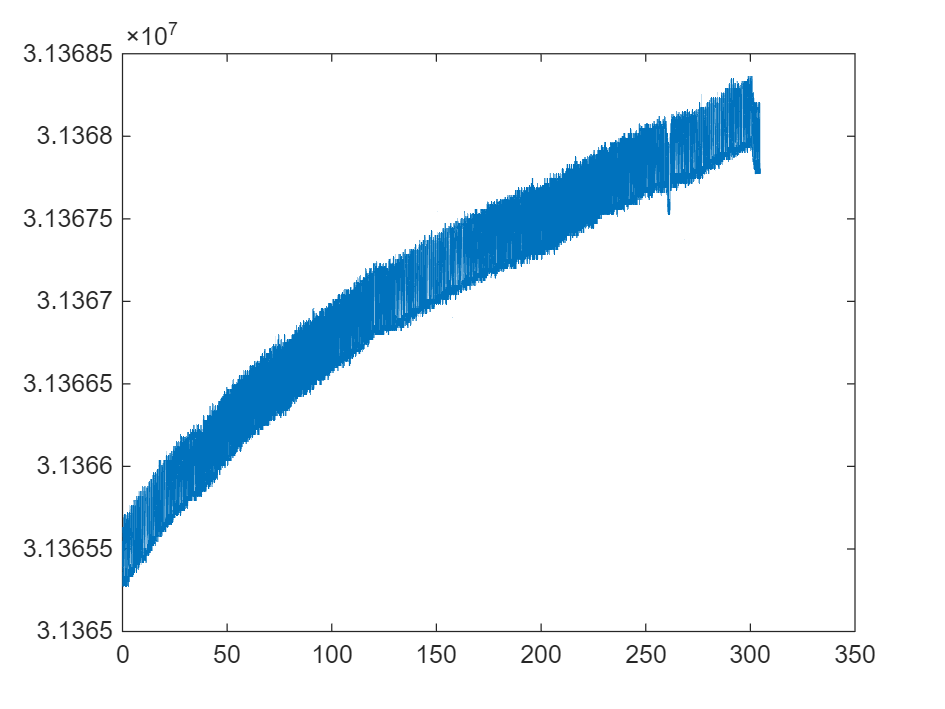

filename = 'freq_change.csv';

raw_data = readtable(filename,'Delimiter',',');

% Take care of header chunk
raw_time = raw_data{:,1};
[row, ~] = find(isnan(raw_time));

if ~isempty(row)
    % double check to make sure nan is from the header instead of data
    if (row(end) - row(1) + 1) == length(row)

        raw_data = raw_data(row(end)+1:end,:); % clip header
    end
end
raw_data(end,:) = [];   % get rid of last line in case of incomplete data log

% Raw time & data
time = raw_data{:,1}./1000; % in seconds
data = raw_data{:,2};

figure;
plot(time,data);


time_diff = time(2:end) - time(1:end-1);
ts = mean(time_diff)

ts = 0.0300

std_ts = std(time_diff)

std_ts = 9.9224e-06

fs = 1./ts

fs = 33.3332

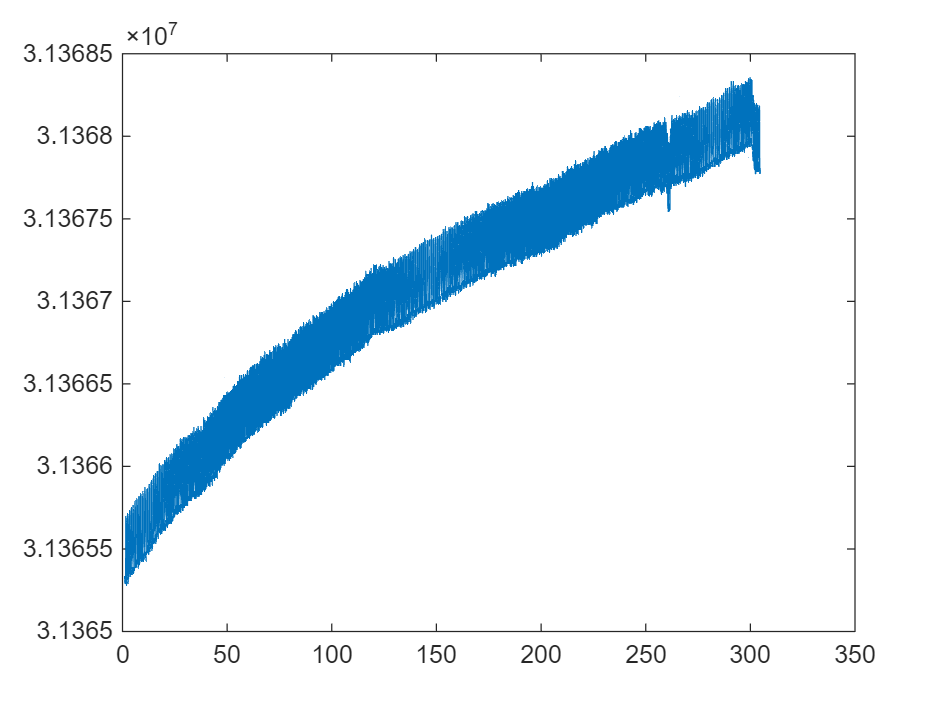


rs_time = 1:0.03:350;

[~,idx] = min(abs(rs_time - time(end)));

rs_time  = rs_time(1:idx);
rs_data = interp1(time,data,rs_time);

figure;
plot(rs_time,rs_data)

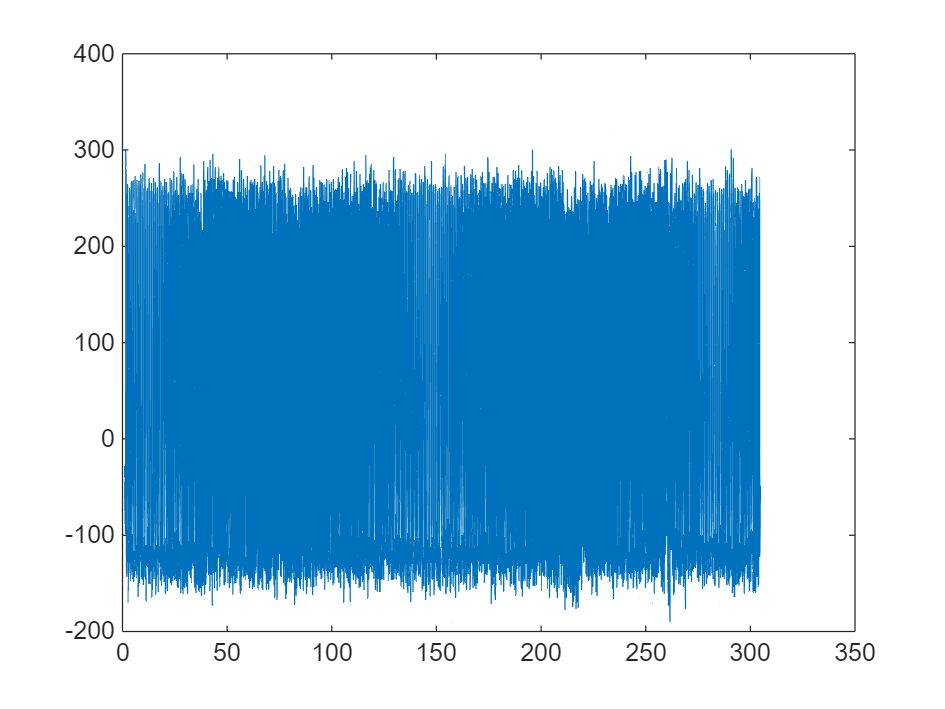

% High pass to try to remove baseline

cutoff_freq = 0.3;    % Cutoff frequency in Hz
filter_order = 4;    % Filter order (adjust as needed)

% lpf = designfilt('lowpassiir', ...
%     'FilterOrder', filter_order, ...
%     'HalfPowerFrequency', cutoff_freq, ...
%     'SampleRate', fs, ...
%     'DesignMethod', 'butter');

[b, a] = butter(filter_order, cutoff_freq/(fs/2), 'high');
hp_data= filtfilt(b, a, rs_data);

figure;
plot(rs_time,hp_data)

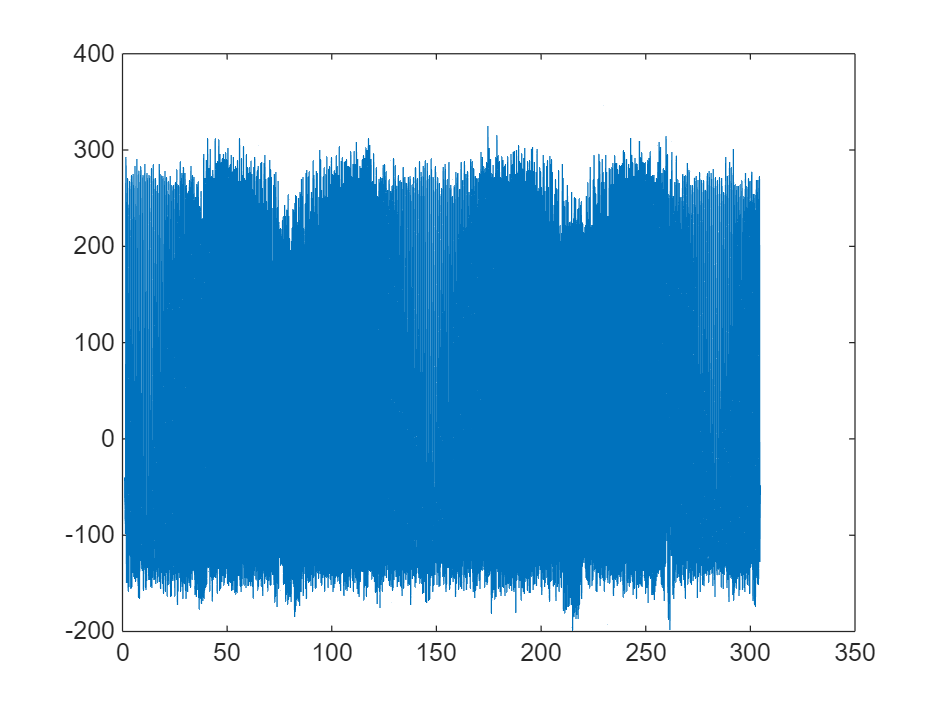

% Low pass to try to remove noise

cutoff_freq = 6;    % Cutoff frequency in Hz
filter_order = 4;    % Filter order (adjust as needed)

% lpf = designfilt('lowpassiir', ...
%     'FilterOrder', filter_order, ...
%     'HalfPowerFrequency', cutoff_freq, ...
%     'SampleRate', fs, ...
%     'DesignMethod', 'butter');

[b, a] = butter(filter_order, cutoff_freq/(fs/2), 'low');
bp_data= filtfilt(b, a, hp_data);

figure;
plot(rs_time,bp_data)

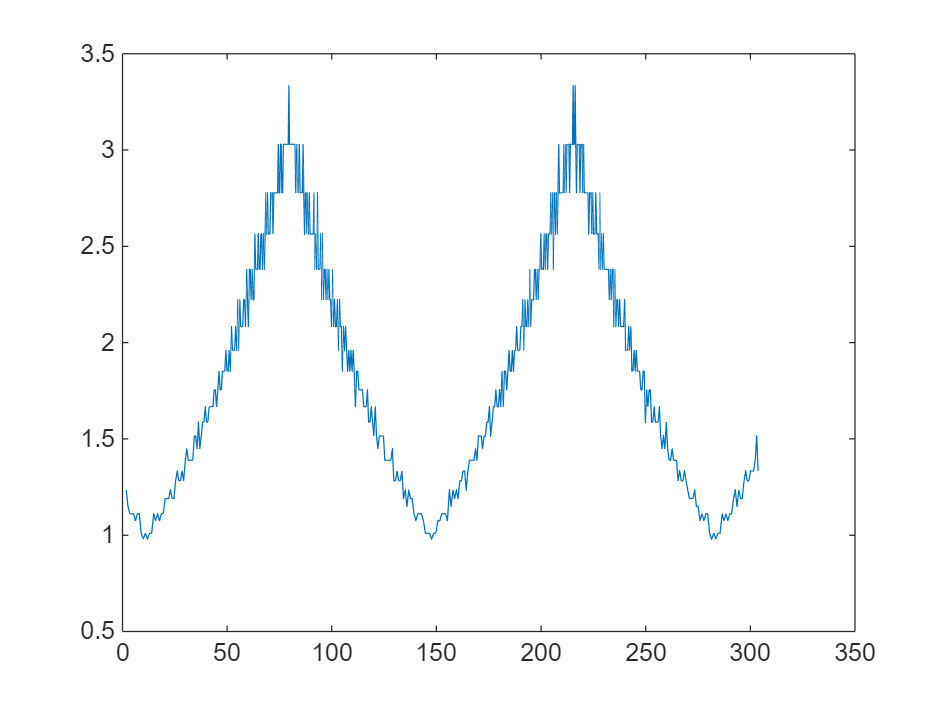

cross_idx = find(bp_data(1:end-1).*bp_data(2:end) < 0 );
time_cross = rs_time(cross_idx);
data_cross = bp_data(cross_idx);
pos_cross_idx = find(data_cross > 0);
pos_time_cross = time_cross(pos_cross_idx);
cross_time_diff = pos_time_cross(2:end) - pos_time_cross(1:end-1);
cross_freq = 1./ cross_time_diff;
figure;
plot(pos_time_cross(1:end-1),cross_freq)

% Ground Truth
pos_freq = round(1:0.1:3.1, 1);
rev_freq = round(3:-0.1:1.1, 1);
freq = [pos_freq,rev_freq];

rep_freq = repmat(freq,1,3);

t_diff = 1./rep_freq;
t_gt = t_diff .* 6;
cum_t_gt = cumsum(t_gt)+8.49;

imp = zeros(size(rs_time));
addition = 0.1;
for k = 1 : length(cum_t_gt)
    idx = find(rs_time >= cum_t_gt(k), 1, 'first');
    if ~isempty(idx)
        if rep_freq(k) == 3.1
            addition = -0.1;
        end
        if rep_freq(k) == 1
            addition = 0.1;
        end
        
        imp(idx) = imp(idx) + addition;
    end
end
value = cumsum(imp)+1;

value = round(value,1);

cross_clip_ind = pos_time_cross>12 & pos_time_cross< 147;

clip_ind = rs_time>12 & rs_time< 147 

clip_ind = 1×10128 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


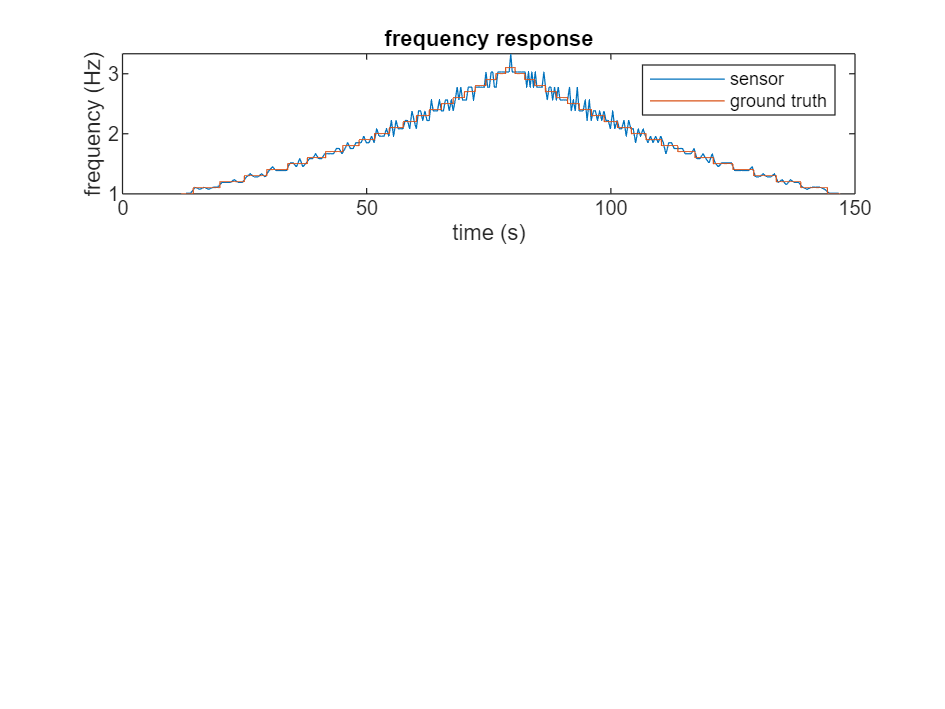


figure;
subplot(3,1,1)
plot(pos_time_cross(cross_clip_ind),cross_freq(cross_clip_ind));
hold on
plot(rs_time(clip_ind),value(clip_ind))
hold off
legend('sensor','ground truth')
ylabel('frequency (Hz)')
xlabel('time (s)')
title('frequency response')

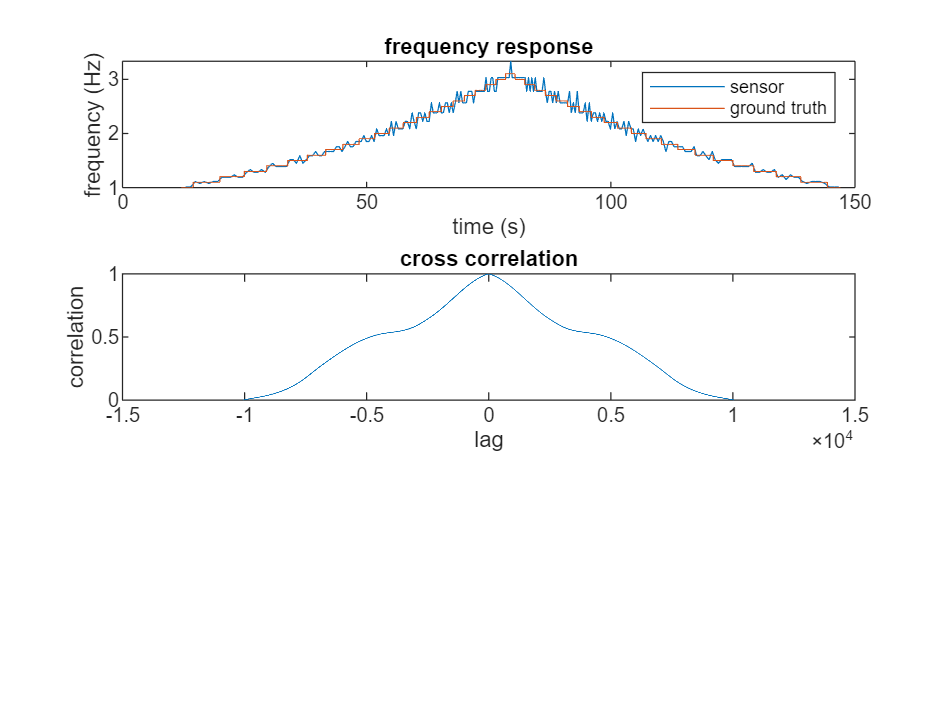

rs_x_freq = interp1(pos_time_cross(1:end-1),cross_freq,rs_time);

nan_ind = find(isnan(rs_x_freq));

value(nan_ind) = [];
rs_x_freq(nan_ind) = [];

[c,lags] = xcorr(rs_x_freq,value,'coeff');
subplot(3,1,2)
plot(lags,c)
xlabel('lag')
ylabel('correlation')
title('cross correlation')

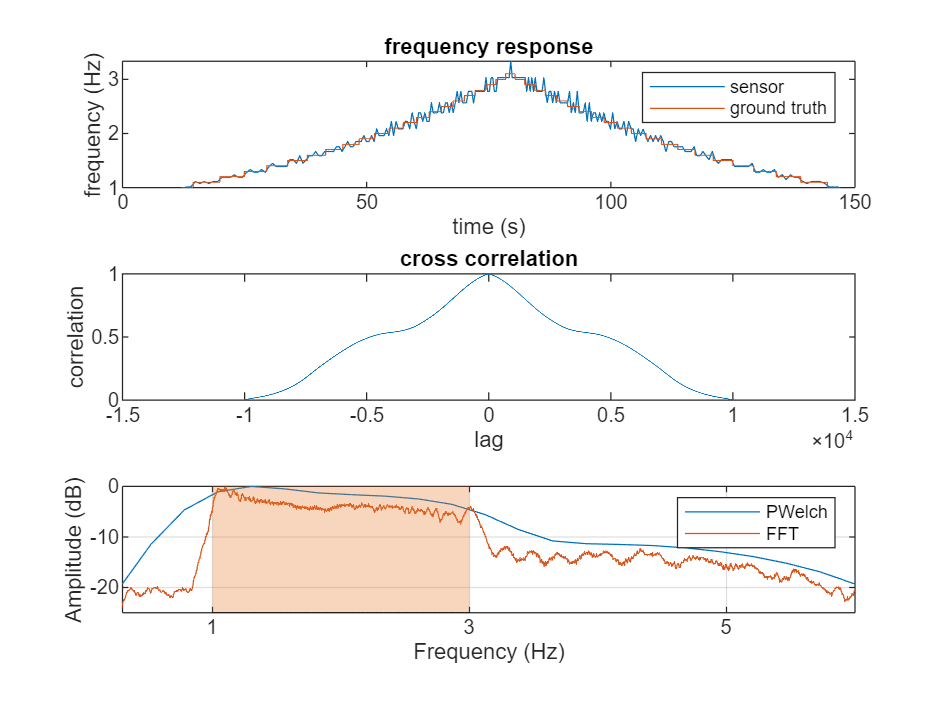

Fs   = 1/0.03;
df = 0.5;
L  = round(Fs/df);

window  = hamming(L);
noverlap = round(0.5*L);
nfft     = 2^nextpow2(L);
[pxx, f] = pwelch(bp_data - mean(bp_data), window, noverlap, nfft, Fs);

N = length(bp_data);
mag_fft = fft(bp_data);
Xmag = abs(mag_fft)./N;
freq_fft = (0:floor(N/2)-1)*(Fs/N);
mag_linear = 2 * Xmag(1:floor(N/2));
mag_smooth = smoothdata(mag_linear, 'movmean', 30); 
mag_db = 20*log10(mag_smooth / max(mag_smooth));

amp = sqrt(pxx);
amp = amp / max(amp);
amp_db = 20*log10(amp);

x = 0:0.01:15;
z = ones(size(x)) * -25;

subplot(3,1,3)
plot(f, amp_db);
hold on
plot(freq_fft,mag_db);
area(x(x>=1&x<=3),z(x>=1&x<=3),"FaceColor","#E97729","FaceAlpha",0.3);
hold off
xlabel('Frequency (Hz)');
ylabel('Amplitude (dB)');
legend('PWelch','FFT')
xticks([1,3, 5, 10, 15])
xlim([0.3,6])
ylim([-25 0])
grid on;